# Testing

Define a arbitrary spectrum function

lambda=0.01; %=wvt.g/wvt.f;
A=3.8;
S= @(k) A./((k.^2 + lambda^2).^(2))

S = function_handle with value:
    @(k)A./((k.^2+lambda^2).^(2))


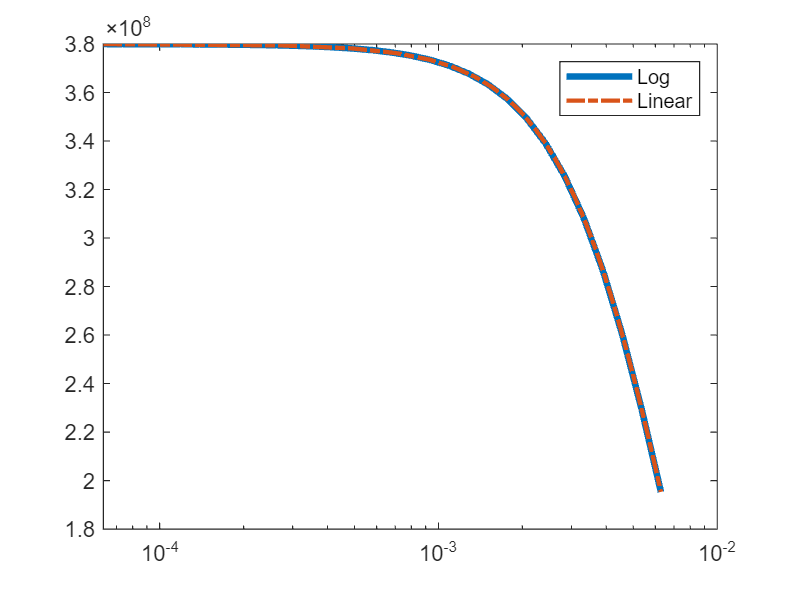




wavelengthLog = exp(linspace(log(1e3), log(1e5), 30))';
KRadialLog=fliplr(2*pi./wavelengthLog);
KRadialLinear=linspace((2*pi)/10^5,(2*pi)/10^3,30)';

%KRadialLog = exp(linspace(log((2*pi)*1e-5), log(2*pi*1e-3), 30))';
%wavelengthLog=logspace(3,5,30)';     
%KRadialLog=((2*pi)./wavelengthLog);

clf
semilogx(KRadialLog',S(KRadialLog'),LineWidth=3)
hold on
semilogx(KRadialLinear',S(KRadialLinear'),LineWidth=2,LineStyle="-.")
legend('Log','Linear')

dk = KRadialLinear(2)-KRadialLinear(1);
for indK = 1:length(KRadialLinear)
    % if indK == 1
    %     % First Interval
    %     lowerBound = 0;  
    %     upperBound = KRadialLinear(indK)/2;
    % elseif indK == length(KRadialLinear)
    %     % Last Interval
    %     lowerBound = upperBound;
    %     upperBound = KRadialLinear(indK);
    % else
    %     % Others Intervals
    %     lowerBound = upperBound;
    %     upperBound = KRadialLinear(indK) + (KRadialLinear(indK + 1) - KRadialLinear(indK))/2;
    % end

    sigma2_current = integral(@(k) S(k),max(KRadialLinear(indK)-dk/2,0),KRadialLinear(indK)+dk/2);
    SLinear(indK)=sigma2_current/dk;       
end

%Power spectrum density
for indK = 1:length(KRadialLog)
    if indK == 1
        % First Interval
        lowerBound = 0;  
        upperBound = KRadialLog(indK)/2;
    elseif indK == length(KRadialLog)

        % Last Interval
        lowerBound = upperBound;
        upperBound = KRadialLog(indK);
    else
        % Others Intervals
        lowerBound = upperBound;
        upperBound = KRadialLog(indK) + (KRadialLog(indK + 1) - KRadialLog(indK))/2;
    end

    
    sigma2_current = integral(@(k) S(k),lowerBound, upperBound);
    SLog(indK)=sigma2_current/(upperBound-lowerBound);       
    
end

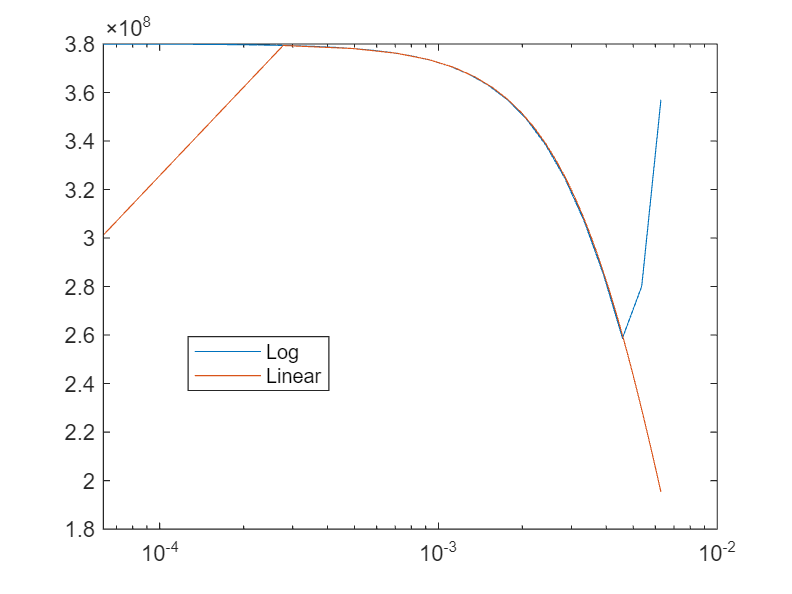

clf

semilogx(KRadialLog',SLog)
hold on
semilogx(KRadialLinear,SLinear)
legend('Log','Linear')